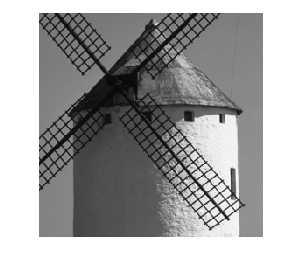

%imwrite(b11, ’b11.tif’, ’Resolution’, 150);
%Kommandot sparar bilden med upplösningen 150 dots (eller pixlar)/tum 
% i tif format
clear;
kvarn = imread('kvarn.tif');
kvarn = im2double(kvarn);
imshow(kvarn);

% 1.1 
b11 = (kvarn >= 0.5)

b11 = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

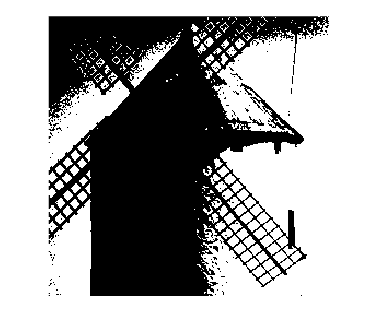

imshow(b11)

imwrite(b11, 'b11.tif', 'Resolution', 150);

% 1.2
load('troskelmatriser.mat')
tr1 = tr1/19

tr1 =     0.4737    0.3684    0.4211    0.5263    0.6316    0.5789
    0.3158    0.0526    0.1053    0.6842    0.9474    0.8947
    0.2632    0.2105    0.1579    0.7368    0.7895    0.8421
    0.5263    0.6316    0.5789    0.4737    0.3684    0.4211
    0.6842    0.9474    0.8947    0.3158    0.0526    0.1053
    0.7368    0.7895    0.8421    0.2632    0.2105    0.1579


tr2 = tr2/33

tr2 =     0.4242    0.3636    0.3939    0.4848    0.5758    0.6364    0.6061    0.5152
    0.1515    0.1212    0.0909    0.3030    0.8485    0.8788    0.9091    0.6970
    0.1818    0.0303    0.0606    0.3333    0.8182    0.9697    0.9394    0.6667
    0.2727    0.2121    0.2424    0.4545    0.7273    0.7879    0.7576    0.5455
    0.5758    0.6364    0.6061    0.5152    0.4242    0.3636    0.3939    0.4848
    0.8485    0.8788    0.9091    0.6970    0.1515    0.1212    0.0909    0.3030
    0.8182    0.9697    0.9394    0.6667    0.1818    0.0303    0.0606    0.3333
    0.7273    0.7879    0.7576    0.5455    0.2727    0.2121    0.2424    0.4545


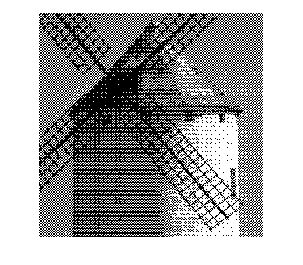

b12_tr1 = troskel(kvarn, tr1);
imshow(b12_tr1)

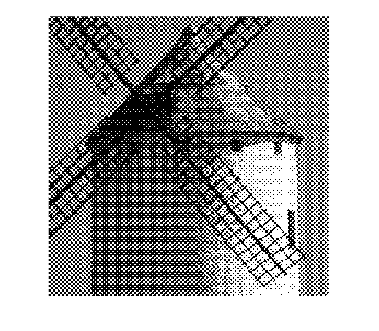

b12_tr2 = troskel(kvarn, tr2);
imshow(b12_tr2)

imwrite(b12_tr1, 'b12_tr1.tif', 'Resolution', 150);
imwrite(b12_tr2, 'b12_tr2.tif', 'Resolution', 150);

% 1.3
tr3 = tr3/33

tr3 =     0.0303    0.9091    0.2424    0.8485    0.0606    0.8788    0.2121    0.8182
    0.5152    0.2727    0.7273    0.4848    0.5455    0.3030    0.6970    0.4545
    0.1515    0.7576    0.0909    0.9697    0.1818    0.7879    0.1212    0.9394
    0.6364    0.3939    0.5758    0.3333    0.6667    0.4242    0.6061    0.3636
    0.0606    0.8788    0.2121    0.8182    0.0303    0.9091    0.2424    0.8485
    0.5455    0.3030    0.6970    0.4545    0.5152    0.2727    0.7273    0.4848
    0.1818    0.7879    0.1212    0.9394    0.1515    0.7576    0.0909    0.9697
    0.6667    0.4242    0.6061    0.3636    0.6364    0.3939    0.5758    0.3333


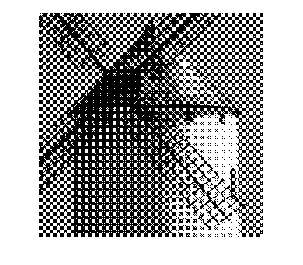

b13 = troskel(kvarn, tr3);
imshow(b13)

imwrite(b13, 'b13.tif', 'Resolution', 150);

% 1.4
linje = [1, 2, 3, 4;
    5, 6, 7, 8;
    9, 10, 11, 12;
    13, 14, 15, 16]/17;
spiral = [10, 9, 8, 7;
        11, 2, 1, 6;
        12, 3, 4, 5;
        13, 14, 15, 16] / 17;

b14_linje = troskel(kvarn, linje)

b14_linje = 512×512 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   0   0   0   1   1   1   1   1   1
   1   1   1   0   1   1   1   0   1   0   0   0   1   0   0   0   0   0   0   0   1   0   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0  

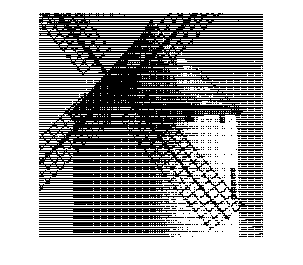

imshow(b14_linje)

imwrite(b14_linje, 'b14_linje.tif', 'Resolution', 150);

b14_spiral = troskel(kvarn, spiral)

b14_spiral = 512×512 logical array
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   1   1   1   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   1   0   0   0   1   0   0   1   1   1   0   1
   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   0   0   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0 

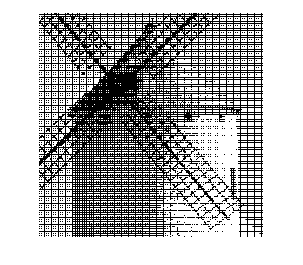

imshow(b14_spiral)

imwrite(b14_spiral, 'b14_spiral.tif', 'Resolution', 150);

% 2.1
b21 = tabellrast(kvarn)

b21 = 512×512 logical array
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   1   1   1   0   1   1   1   0   0   1   1   0   0   1   1   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   1   0   0   0   1   0   0   0   1   1   0   1   1
   1   1   1   0   1   1   1   0   0   1   1   0   0   0   1   0   0   0   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0

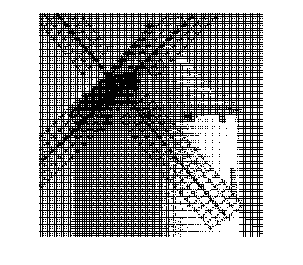

imshow(b21)

imwrite(b21, 'b21.tif', 'Resolution', 150);

% 2.2
b22 = tabellrast2(kvarn)

b22 = 512×512 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0

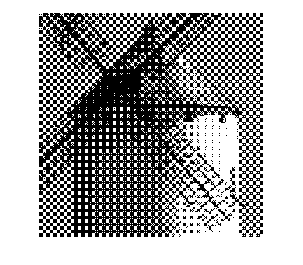

imshow(b22)

imwrite(b22, 'b22.tif', 'Resolution', 150);

% 2.3
b24 = tabellrast3(kvarn)

b24 = 1024×1024 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   1   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   1   0   1  

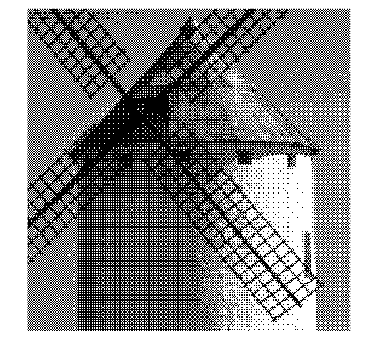

imshow(b24)

imwrite(b24, 'b24.tif', 'Resolution', 150);
whos b24

  Name         Size                Bytes  Class      Attributes

  b24       1024x1024            1048576  logical              



% 3.1
filt1 = [0 0 7;
        3 5 1]/16;
b31 = errordif(kvarn, filt1)

b31 =      0     1     0     1     0     1     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     1     0     1     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1
     0     1     0     0     1     0     1     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0 

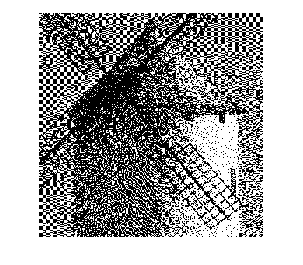

imshow(b31)

imwrite(b31, 'b31.tif', 'Resolution', 150);

% 3.2
filt2 =  [0 0 0 7 5;
        3 5 7 5 3;
        1 3 5 3 1]/48;
b32 = errordif(kvarn, filt2)

b32 =      0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     1     0     1     0     1     1     0     1     0     0     0     0     1     0     1     0     0     0     0     0     1     0     1     1     0     1     1     0     1     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1
     0     1     0     0     1     0     0     1     1     0     0     0     0     0     0     0     0     0     1     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     0     1     0     1     1     0     0     0     0     0 

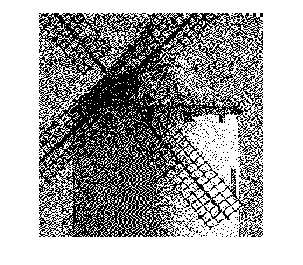

imshow(b32)

imwrite(b32, 'b32.tif', 'Resolution', 150);

% 3.4
filt3 = [0;
        1];
filt4 = [0 0 1;
        0 1 0]/2;

b34_f3 = errordif(kvarn, filt3)

b34_f3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0
     1     1     1     1     1     1     1     1     0     0     1     1     0     0    

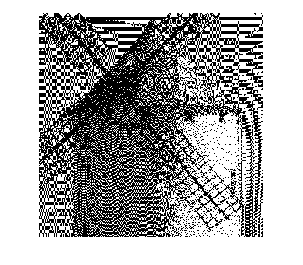

imshow(b34_f3)

imwrite(b34_f3, 'b34_f3.tif', 'Resolution', 150);

b34_f4 = errordif(kvarn, filt4)

b34_f4 =      0     1     0     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     1     0     1     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1
     0     1     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     1     0     1     0     0     0     1     1     0     1     0     0     0     0    

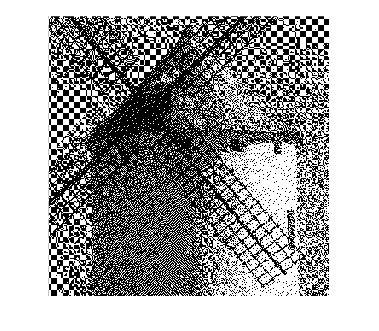

imshow(b34_f4)

imwrite(b34_f4, 'b34_f4.tif', 'Resolution', 150);

% 3.6
k = 0.4

k = 0.4000

noise = (rand(512, 512) - 0.5) * k

noise =    -0.1961   -0.1922   -0.0196    0.1240    0.1216   -0.1797   -0.0855   -0.0375    0.1543    0.0354   -0.0680    0.0638   -0.0612    0.1701    0.0199   -0.0903   -0.1885    0.1544    0.0506    0.0524   -0.0159   -0.1414   -0.1158   -0.0485    0.0561    0.1645    0.1141    0.1809    0.1483    0.1307    0.1640    0.1456    0.1802   -0.1830   -0.1382    0.0892    0.1068    0.0675    0.1626   -0.0660    0.1775    0.1959    0.0518    0.0966    0.1607   -0.1013   -0.0803   -0.1514   -0.1754    0.1324
   -0.1944   -0.1738   -0.1032    0.1012    0.0872    0.0983   -0.0067   -0.0452   -0.1235    0.0646    0.0959    0.1659   -0.0505    0.0294   -0.0763   -0.0514   -0.1125    0.0729   -0.0662    0.0081    0.1130    0.1032   -0.0334    0.0956    0.0104   -0.0790   -0.0382    0.1224    0.0830   -0.1959   -0.1523    0.0705   -0.0153   -0.1405    0.1246   -0.0771   -0.1185    0.1960   -0.1920    0.1538    0.0161   -0.1150   -0.2000   -0.0420   -0.0739   -0.1449    0.0214   -0.1328   -0.0763 

b36 = kvarn + noise

b36 =     0.2627    0.2666    0.4353    0.5789    0.5765    0.2752    0.3616    0.4096    0.4524    0.3334    0.0340    0.1658    0.2330    0.4642    0.4278    0.3175   -0.0042    0.3387    0.1761    0.1779    0.3292    0.2037    0.3430    0.4103    0.5149    0.6233    0.5730    0.6397    0.6032    0.5856    0.6229    0.6044    0.6429    0.2797    0.0971    0.3245    0.1774    0.1381    0.2293    0.0007    0.2402    0.2586    0.1342    0.1789    0.3842    0.1222    0.3393    0.2682    0.2834    0.5913
    0.2644    0.2850    0.3517    0.5561    0.5421    0.5532    0.4404    0.4019    0.1745    0.3626    0.1979    0.2678    0.2436    0.3235    0.3316    0.3564    0.0718    0.2572    0.0592    0.1336    0.4581    0.4483    0.4254    0.5544    0.4692    0.3799    0.4206    0.5812    0.5379    0.2590    0.3065    0.5293    0.4474    0.3223    0.3599    0.1582   -0.0479    0.2666   -0.1253    0.2204    0.0788   -0.0523   -0.1176    0.0403    0.1497    0.0786    0.4410    0.2868    0.3825   

b36 = errordif(b36, filt1)

b36 =      0     0     1     0     1     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     1     0     1     1     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     1     0     0     1     0     0     0     1     0     1     0     0     0     1     0     0     0     0     0     0     0     0     1     0     1     0
     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     1     0     1     1     0     1     0     1     0     0     0     1     1     0     0     0     0     0     1     0     0     0     0     0     1     0     1
     1     0     1     0     1     1     0     1     1     1     0     0     1     0     0 

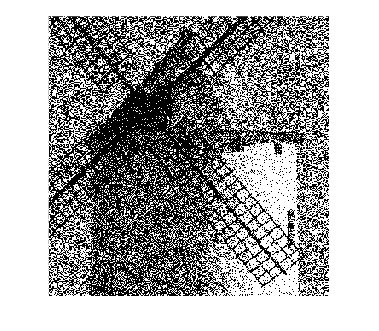

imshow(b36)

imwrite(b36, 'b36.tif', 'Resolution', 150);

% 4
b40 = imcdp(kvarn)

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here8
here10
here16
here6
here17
here5
here7
here4
here18
here1
here11
here3
here2
here12
here15


b40 =      0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     1     0     1     1     1     1     0     1     1     1     1     1     1     1     0     0
     0     1     0     1     1     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     0     1     0     1     1     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1
     0     1     0     1     0     0     0     1     1     0     1     0     0     0     0     0     0     0     0     1     0     1     1     0     1     0     1     1     0     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     1     0     1     0     0     0     1     0     0     1     0     0 

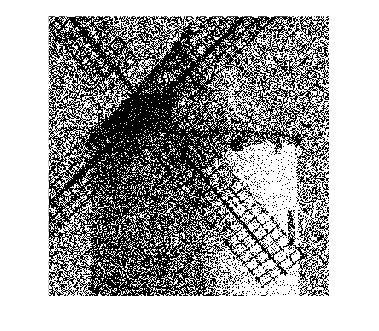

imshow(b40)

imwrite(b40, 'b40.tif', 'Resolution', 150);